## `PS4`

`刘沛雨 2100012289 信息科学技术学院`

`本次作业由自己独立完成`

## Exercise 1

﻿Let’s study the gene regulatory network in [EG] Chap 4.3:

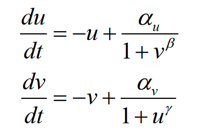

﻿The nullclines are plotted in Figure 4.8 for three values of $\alpha =\alpha_u =\alpha_v$. Write a MATLAB code to reproduce figure 4.8c. Then plot on the same axes, superimpose the direction fields. Plot three trajectories starting from (0,0), (0.5,0) and (0,0.5), for a time range that you think best represents the dynamics. ﻿For each of the equilibrium solution, compute the eigenvalues that determine the stability of that equilibrium by 1) computing the Jacobian matrix at each equilibrium point and then 2) computing the eigenvalues of this matrix. Describe your results for each equilibrium concisely. (Can you classify each of the points?)

#### 复现图4.8c，绘制方向场

% 参数设置
a = 3;
b = 2;
u = 0: 0.01: 4;

% 复现图4.8c
figure;
plot(u, a ./ (1 + u .^ b), '-', 'LineWidth', 2);
ylim([0, 4]);
hold on;
plot(u, sqrt(a ./ u - 1), '-', 'LineWidth', 2); % 以u为自变量

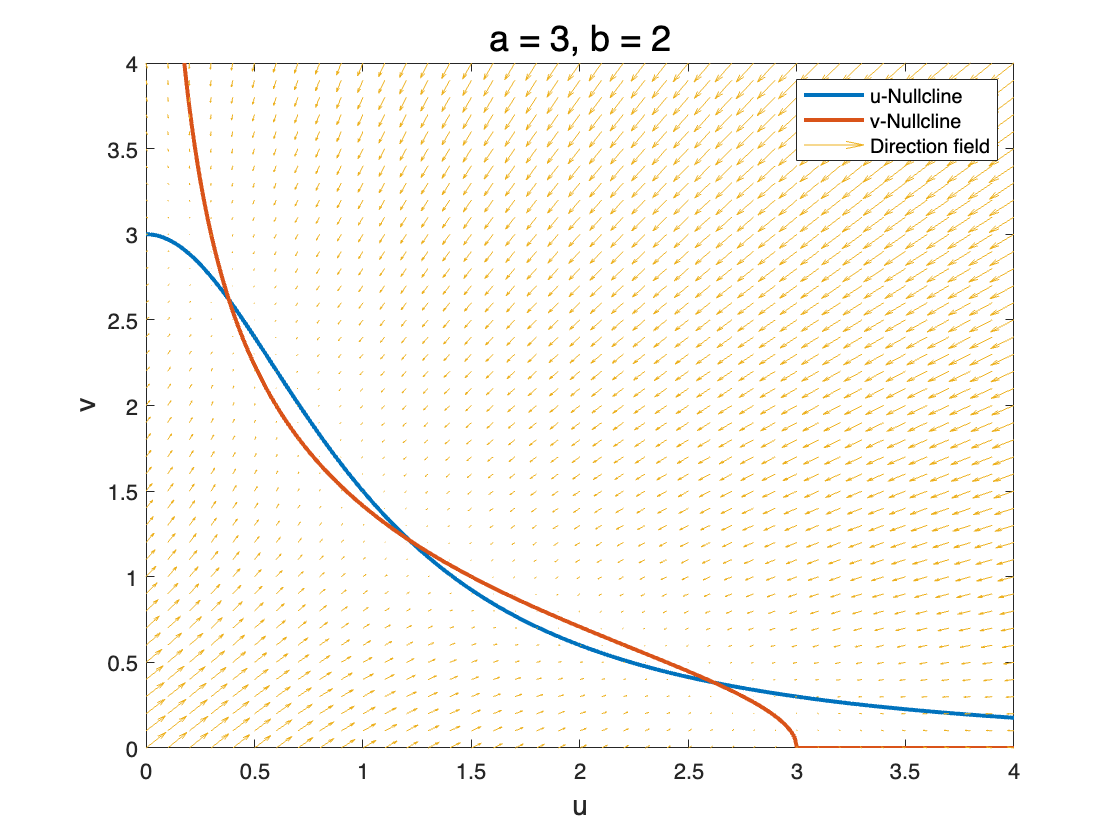

xlabel('u', 'FontSize', 14);
ylabel('v', 'FontSize', 14);
title('a = 3, b = 2', 'FontSize', 18);

% 绘制方向场
[u, v] = meshgrid(0:0.1:4, 0:0.1:4);
du_dt = -u + a ./ (1 + v.^b);
dv_dt = -v + a ./ (1 + u.^b);
quiver(u, v, du_dt, dv_dt, 1.2);
legend('u-Nullcline', 'v-Nullcline', 'Direction field');

#### 轨迹绘制

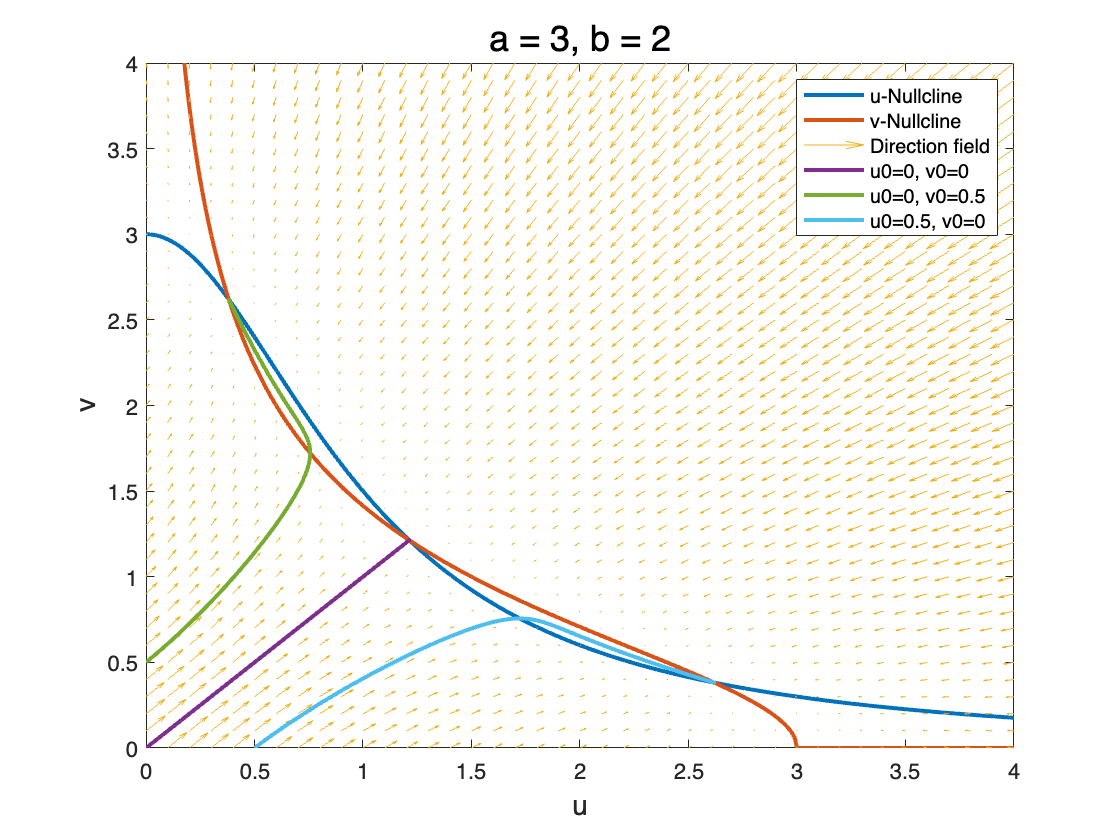

x0 = [0, 0; 0, 0.5; 0.5, 0];
fun = @(t, x) [-x(1) + a / (1 + x(2)^b); -x(2) + a / (1 + x(1)^b)];
tspan = [0 100];
for i = 1:3
    [~, x] = ode45(fun, tspan, x0(i,:)); % 给定u0,v0, 用ode求解器计算u, v
    plot(x(:, 1), x(:, 2), 'LineWidth', 2);
end
legend('u-Nullcline', 'v-Nullcline', 'Direction field', 'u0=0, v0=0', 'u0=0, v0=0.5', 'u0=0.5, v0=0');

#### 平衡点稳定性分析

% 数值方法求出平衡点的坐标
fun = @(x) [-x(1) + a / (1 + x(2)^b); -x(2) + a / (1 + x(1)^b)];
options = optimoptions('fsolve', 'Display', 'off');
initial_guesses = [1.2, 1.2; 0.4, 2; 2, 0.4]; % 不同初始猜测以找到所有平衡点
eq_points = zeros(size(initial_guesses));
for i = 1:size(initial_guesses, 1)
    eq_points(i, :) = fsolve(fun, initial_guesses(i, :), options);
end

% 对每个平衡点计算对应的雅可比矩阵值
jacobian_matrix = zeros(2, 2, 3);
for i = 1:size(eq_points, 1)
    matrix = zeros(2, 2);
    matrix(1, 1) = -1;
    matrix(1, 2) = -a * (b * eq_points(i, 2) ^ (b - 1)) / ((1 + eq_points(i, 2) ^ b) ^ 2);
    matrix(2, 1) = -a * (b * eq_points(i, 1) ^ (b - 1)) / ((1 + eq_points(i, 1) ^ b) ^ 2);
    matrix(2, 2) = -1;
    jacobian_matrix(:, :, i) = matrix;
end

% 求雅可比矩阵特征值
for i = 1:size(eq_points, 1)
    [V, D] = eig(jacobian_matrix(:, :, i));
    fprintf('Equilibrium solution %d: (%f, %f)', i, eq_points(i, 1), eq_points(i, 2));
    fprintf('Jocobian matrix:');
    disp(jacobian_matrix(:, :, i));
    fprintf('Eigenvalue:');
    disp(D);
end

Equilibrium solution 1: (1.213412, 1.213412)

Jocobian matrix:

   -1.0000   -1.1911
   -1.1911   -1.0000



Eigenvalue:

   -2.1911         0
         0    0.1911



Equilibrium solution 2: (0.381966, 2.618034)

Jocobian matrix:

   -1.0000   -0.2546
   -1.7454   -1.0000



Eigenvalue:

   -0.3333         0
         0   -1.6667



Equilibrium solution 3: (2.618034, 0.381966)

Jocobian matrix:

   -1.0000   -1.7454
   -0.2546   -1.0000



Eigenvalue:

   -0.3333         0
         0   -1.6667



因此，平衡点$\left(1\ldotp 213412,1\ldotp 213412\right)$ 为鞍点，不稳定方向为$u$，平衡点2、3均为稳定点。

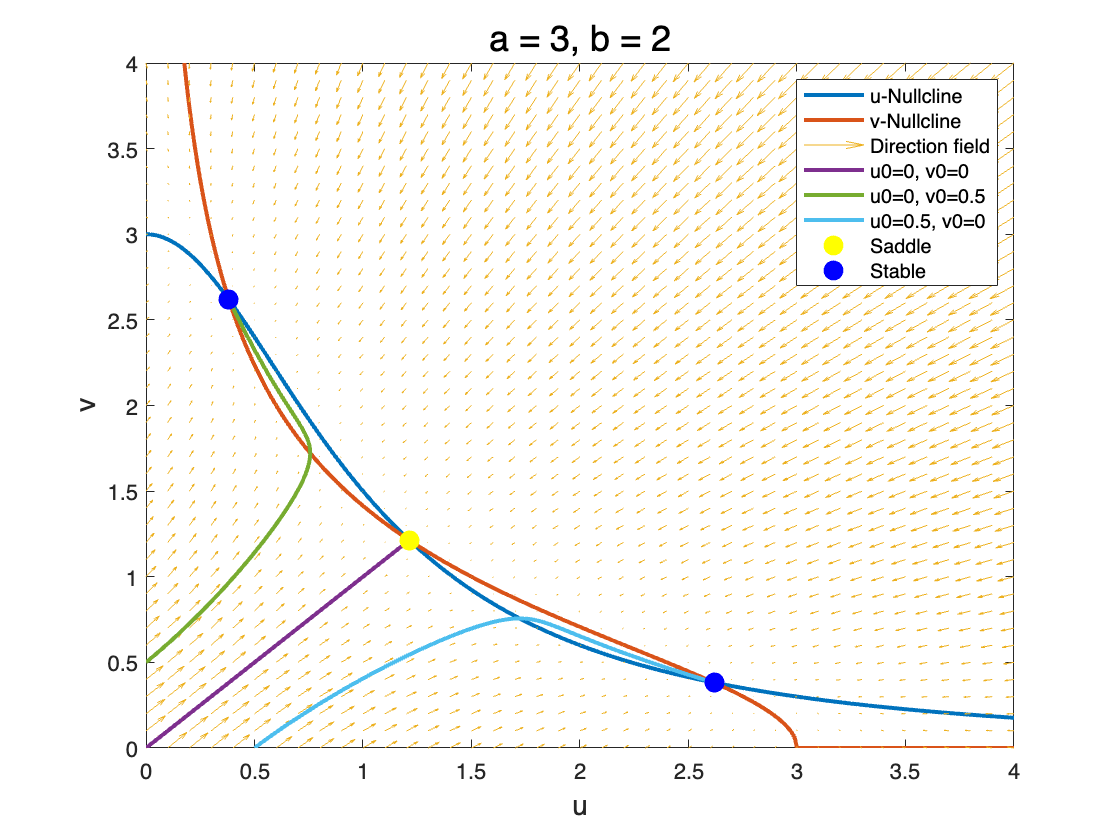

% 平衡点可视化
plot(eq_points(1, 1), eq_points(1, 2), 'y.', 'MarkerSize',30);
plot(eq_points(2, 1), eq_points(2, 2), 'b.', 'MarkerSize',30);
plot(eq_points(3, 1), eq_points(3, 2), 'b.', 'MarkerSize',30);
legend('u-Nullcline', 'v-Nullcline', 'Direction field', 'u0=0, v0=0', 'u0=0, v0=0.5', 'u0=0.5, v0=0', 'Saddle', 'Stable');
hold off

## Exercise 2

﻿Compute another phase portrait for the Morris-Lecar model with parameter values $v_1 =-1\ldotp 2$, $v_2 =18$, $v_3 =2$, $v_4 =30$, $g_{\textrm{Ca}} =5\ldotp 5$, $g_K =8$, $g_L =2$, $v_K =-84$, $v_L =-60$, $v_{\textrm{Ca}} =120$, $C=20$, $\phi =0\ldotp 22$ and $i=91$. Only the parameter $i$ has changed from those used in Figure 5.12. In what ways does the phase portrait differ from those displayed in Figures 5.10 and 5.12? In what ways does the phase plane differ from the cases we did in class?

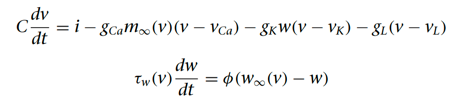

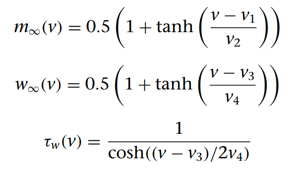

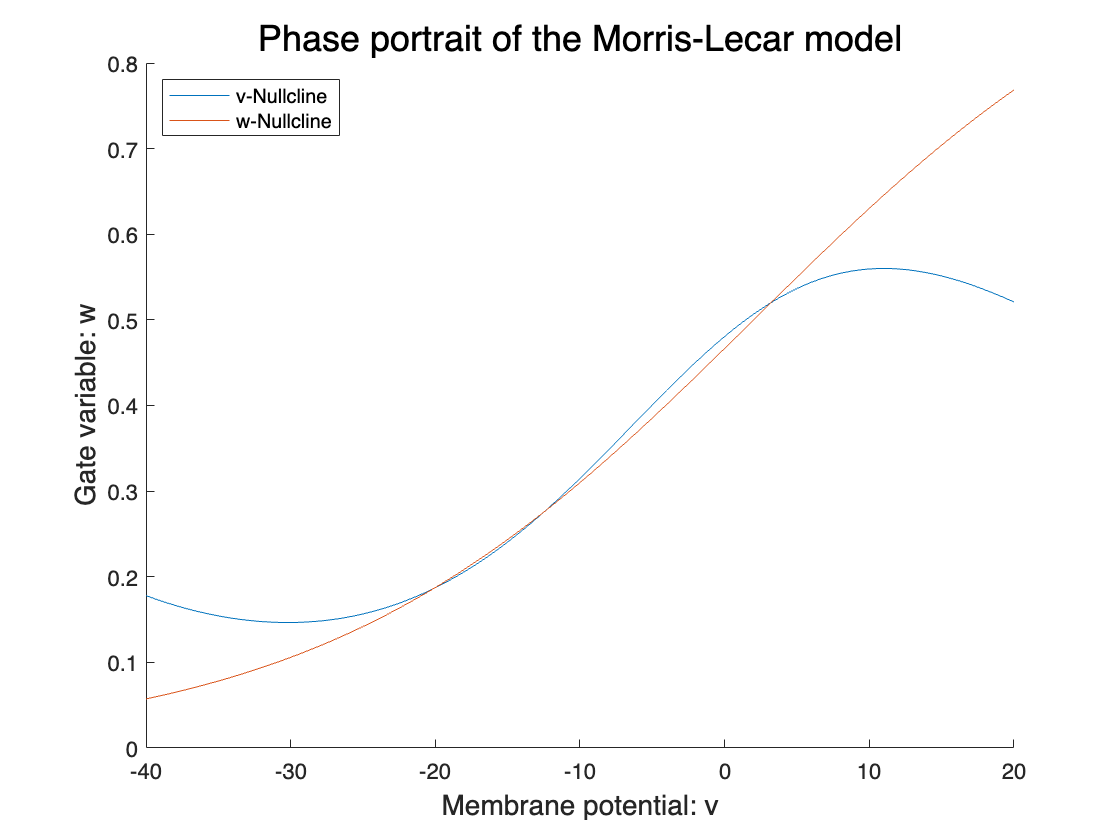

% 定义参数
v1 = -1.2;
v2 = 18;
v3 = 2;
v4 = 30;
g_Ca = 5.5;
g_K = 8;
g_L = 2;
v_K = -84;
v_L = -60;
v_Ca = 120;
C = 20;
fi = 0.22;
i = 91;

% 定义Morris-Lecar模型的微分方程
fun = @(t, x) [(i - g_Ca * (0.5 * (1 + tanh((x(1) - v1) / v2))) * (x(1) - v_Ca) - g_K * x(2) * (x(1) - v_K) - g_L * (x(1) - v_L)) / C; 
    cosh((x(1) - v3) / (2 * v4)) * fi * (0.5 * (1 + tanh((x(1) - v3) / v4)) - x(2))];

% 画线
v = -40: 0.1: 20;
figure;
hold on;
plot(v, (i - g_Ca .* (0.5 .* (1 + tanh((v - v1) ./ v2))) .* (v - v_Ca) - g_L .* (v - v_L)) ./ (g_K .* (v - v_K)), "LineWidth", 0.5);
plot(v, 0.5 * (1 + tanh((v - v3) / v4)), 'LineWidth', 0.5);
xlabel('Membrane potential: v', 'FontSize', 14);
ylabel('Gate variable: w', 'FontSize', 14);
title('﻿Phase portrait of ﻿the Morris-Lecar model', 'FontSize', 18)
legend('v-Nullcline', 'w-Nullcline', 'Location','northwest')

%% 计算平衡点
options = optimoptions('fsolve', 'Display', 'off');
initial_guesses = [-20, 0.18; -15, 0.2; 0.5, 0.5]; % 不同初始猜测以找到所有平衡点
eq_points = zeros(size(initial_guesses));
tmp = @(x) [(i - g_Ca * (0.5 * (1 + tanh((x(1) - v1) / v2))) * (x(1) - v_Ca) - g_K * x(2) * (x(1) - v_K) - g_L * (x(1) - v_L)) / C; 
    cosh((x(1) - v3) / (2 * v4)) * fi * (0.5 * (1 + tanh((x(1) - v3) / v4)) - x(2))];
for i = 1:size(initial_guesses, 1)
    eq_points(i, :) = fsolve(tmp, initial_guesses(i, :), options);
end

% 计算雅可比矩阵
syms x1 x2 i g_Ca v1 v2 v_Ca g_K v_K g_L v_L C v3 v4 fi
x = [x1; x2];
tmp = [(i - g_Ca * (0.5 * (1 + tanh((x1 - v1) / v2))) * (x1 - v_Ca) - g_K * x2 * (x1 - v_K) - g_L * (x1 - v_L)) / C;
       cosh((x1 - v3) / (2 * v4)) * fi * (0.5 * (1 + tanh((x1 - v3) / v4)) - x2)];
J = jacobian(tmp, x);
disp(J);

$$\begin{array}{l} \left(\begin{array}{cc} -\frac{g_{L}+g_{K}\,x_{2}-g_{\mathrm{Ca}}\,\left(\frac{\sigma_{3}}{2}-\frac{1}{2}\right)+\frac{g_{\mathrm{Ca}}\,\left({\sigma_{3}}^{2}-1\right)\,\left(v_{\mathrm{Ca}}-x_{1}\right)}{2\,v_{2}}}{C} & \frac{g_{K}\,\left(v_{K}-x_{1}\right)}{C}\\ \frac{\mathrm{fi}\,\sinh\left(\sigma_{1}\right)\,\left(x_{2}+\frac{\sigma_{2}}{2}-\frac{1}{2}\right)}{2\,v_{4}}-\frac{\mathrm{fi}\,\cosh\left(\sigma_{1}\right)\,\left({\sigma_{2}}^{2}-1\right)}{2\,v_{4}} & -\mathrm{fi}\,\cosh\left(\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{v_{3}-x_{1}}{2\,v_{4}}\\ \sigma_{2}=\tanh\left(\frac{v_{3}-x_{1}}{v_{4}}\right)\\ \sigma_{3}=\tanh\left(\frac{v_{1}-x_{1}}{v_{2}}\right) \end{array}$$

% 计算平衡点处雅可比矩阵的值
params = {v1, v2, v3, v4, g_Ca, g_K, g_L, v_K, v_L, v_Ca, C, fi, i};
values = {-1.2, 18, 2, 30, 5.5, 8, 2, -84, -60, 120, 20, 0.22, 91}; 
x_values = {x1, x2};
jacobian_matrix = zeros(2, 2, 3);

for i = 1:size(eq_points, 1)
    x_num = {eq_points(i, 1), eq_points(i, 2)};
    jacobian_matrix(:, :, i) = double(subs(J, [params, x_values], [values, x_num]));
end

% 计算特征值
for i = 1:size(eq_points, 1)
    [V, D] = eig(jacobian_matrix(:, :, i));
    fprintf('Equilibrium solution %d: (%f, %f)', i, eq_points(i, 1), eq_points(i, 2));
    fprintf('Jocobian matrix:');
    disp(jacobian_matrix(:, :, i));
    fprintf('Eigenvalue:');
    disp(D);
end

Equilibrium solution 1: (-20.144247, 0.185989)

Jocobian matrix:

    0.2103  -25.5423
    0.0024   -0.2352



Eigenvalue:

  -0.0124 + 0.1049i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0124 - 0.1049i



Equilibrium solution 2: (-12.479777, 0.275815)

Jocobian matrix:

    0.4280  -28.6081
    0.0030   -0.2264



Eigenvalue:

    0.2451         0
         0   -0.0435



Equilibrium solution 3: (3.210002, 0.520156)

Jocobian matrix:

    0.3621  -34.8840
    0.0037   -0.2200



Eigenvalue:

   0.0710 + 0.2074i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0710 - 0.2074i



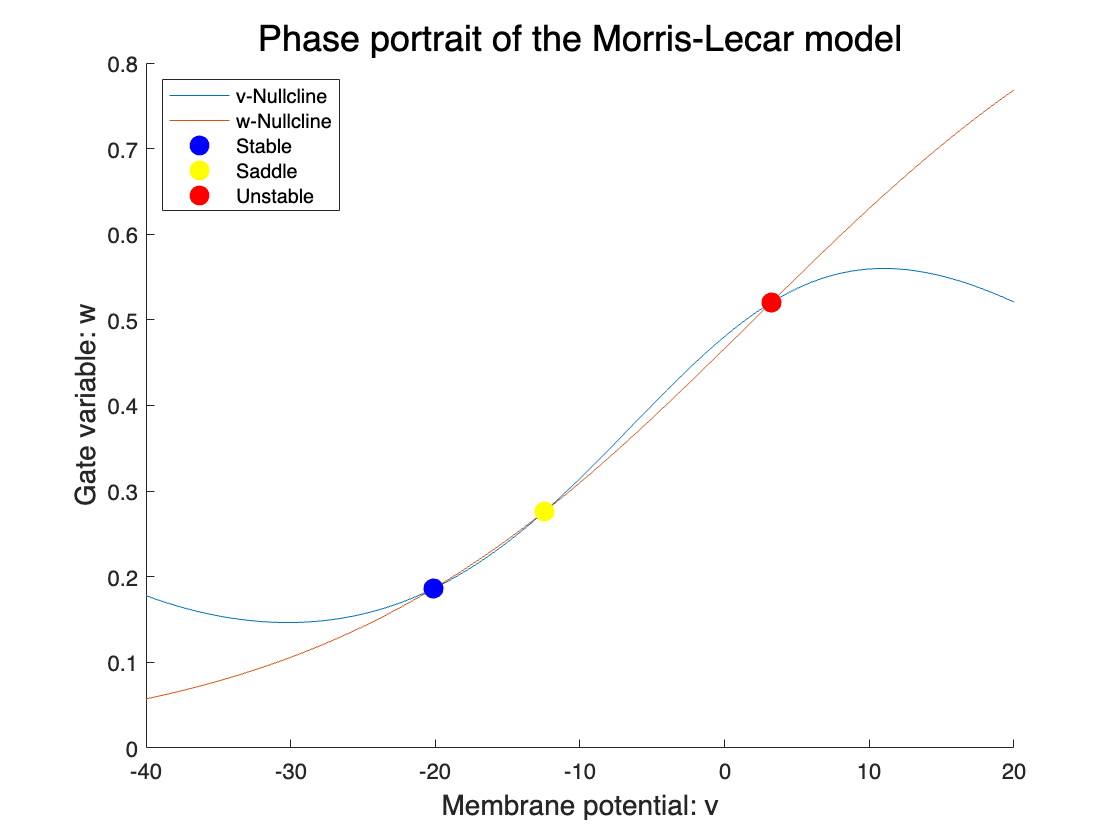

% 平衡点可视化
plot(eq_points(1, 1), eq_points(1, 2), 'b.', 'MarkerSize',30);
plot(eq_points(2, 1), eq_points(2, 2), 'y.', 'MarkerSize',30);
plot(eq_points(3, 1), eq_points(3, 2), 'r.', 'MarkerSize',30);
legend('v-Nullcline', 'w-Nullcline', 'Stable', 'Saddle', 'Unstable', 'Location','northwest');

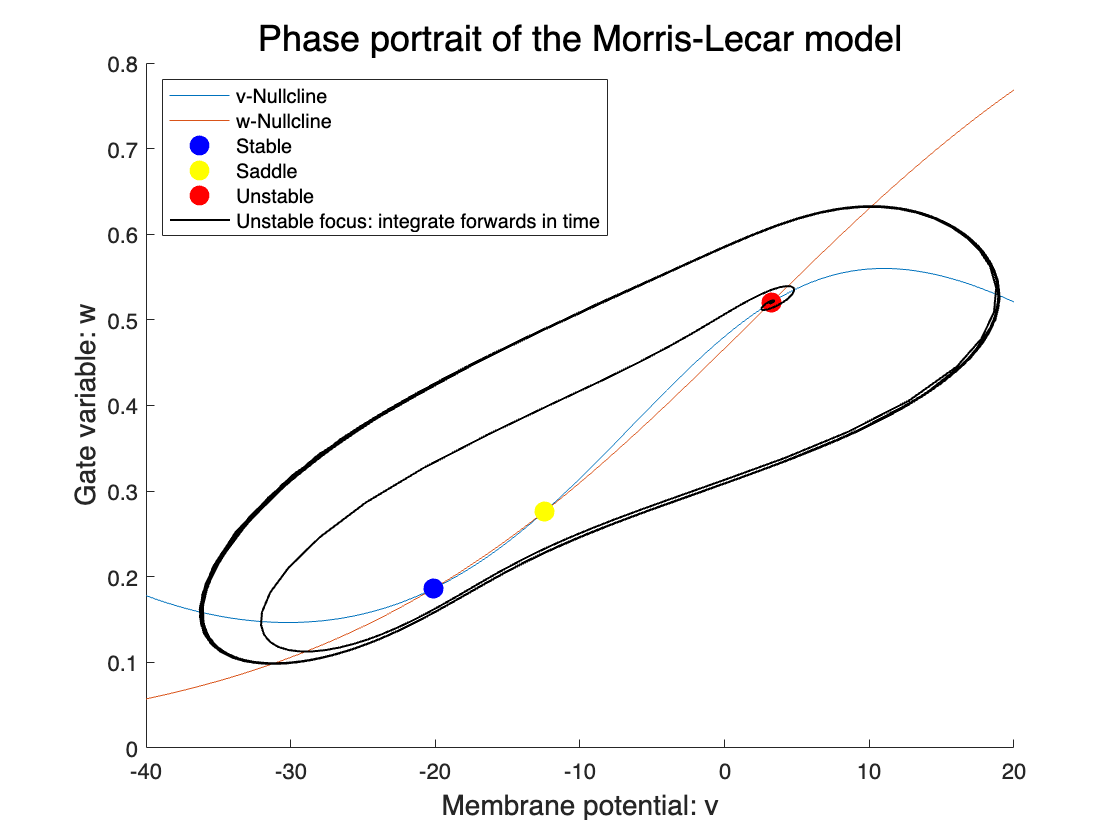

% 计算不稳定点的轨迹
tspan = [0 10000];
x0 = [eq_points(3, 1), eq_points(3, 2)];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'k','LineWidth', 1);
legend('v-Nullcline', 'w-Nullcline', 'Stable', 'Saddle', 'Unstable', '﻿Unstable focus: integrate forwards in time','Location','northwest');

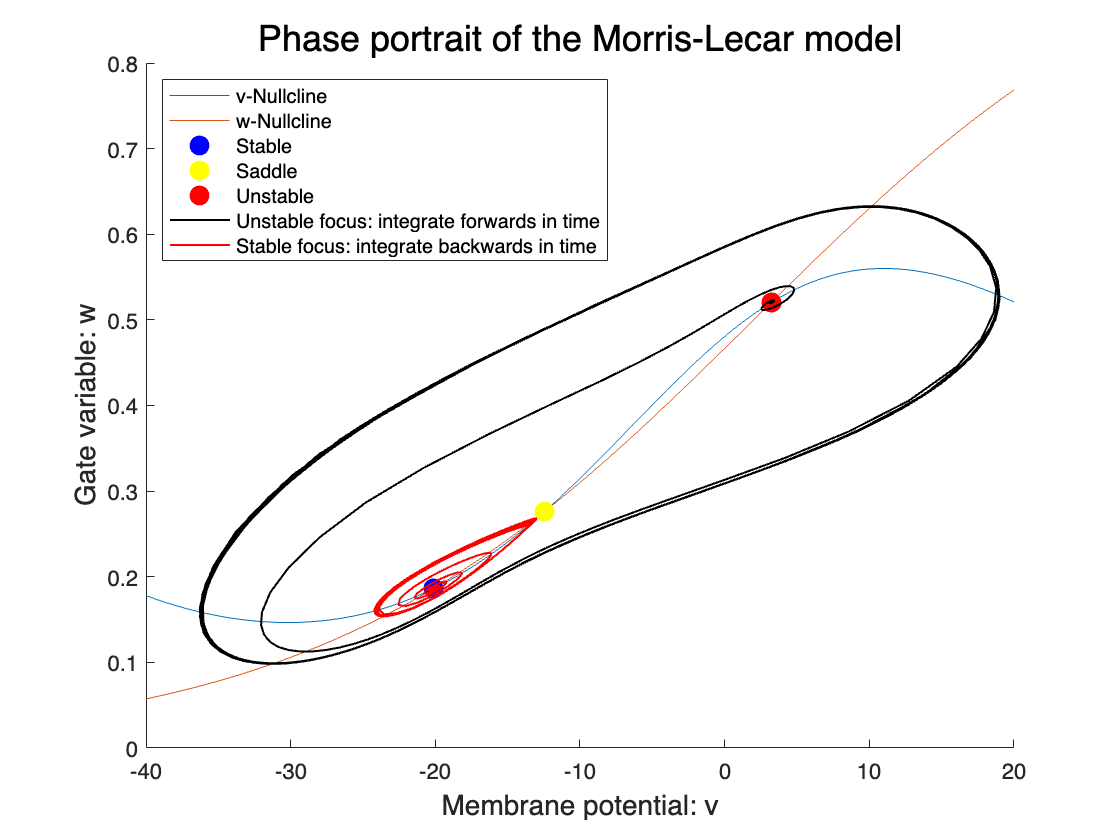

% 计算稳定点的轨迹
tspan = [0, -10000];
x0 = [eq_points(1, 1), eq_points(1, 2)];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'r', 'LineWidth', 1);
legend('v-Nullcline', 'w-Nullcline', 'Stable', 'Saddle', 'Unstable', '﻿Unstable focus: integrate forwards in time', '﻿Stable focus: integrate backwards in time','Location','northwest');

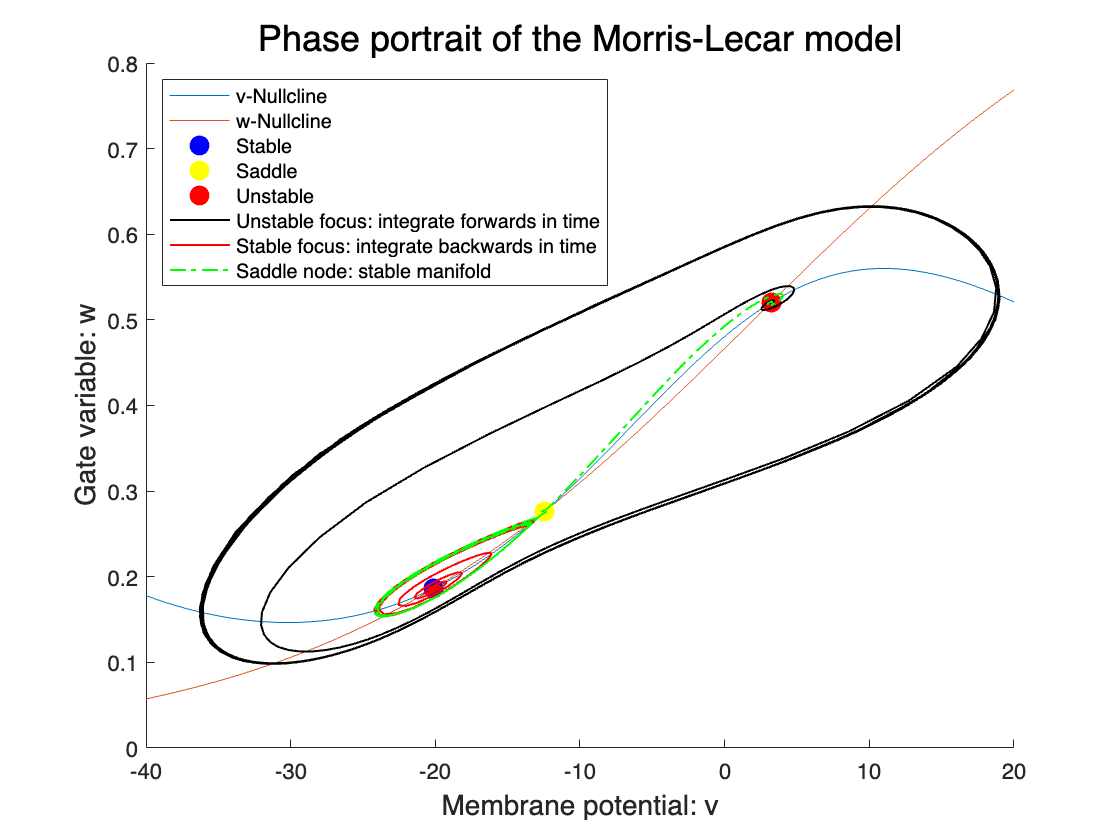

% 计算鞍点的稳定流形（从位于稳定特征向量方向v上鞍点两侧的初始条件计算两个反向轨迹）
tspan = [0 -500];
x0 = [eq_points(2, 1) + 0.2, eq_points(2, 2)];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'g', 'LineWidth', 1 , 'LineStyle','-.');

x0 = [eq_points(2, 1) - 0.2, eq_points(2, 2)];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'g', 'LineWidth', 1, 'LineStyle','-.');


legend('v-Nullcline', 'w-Nullcline', 'Stable', 'Saddle', 'Unstable', '﻿Unstable focus: integrate forwards in time', '﻿Stable focus: integrate backwards in time', ...
    '﻿Saddle node: stable manifold', '', 'Location','northwest');

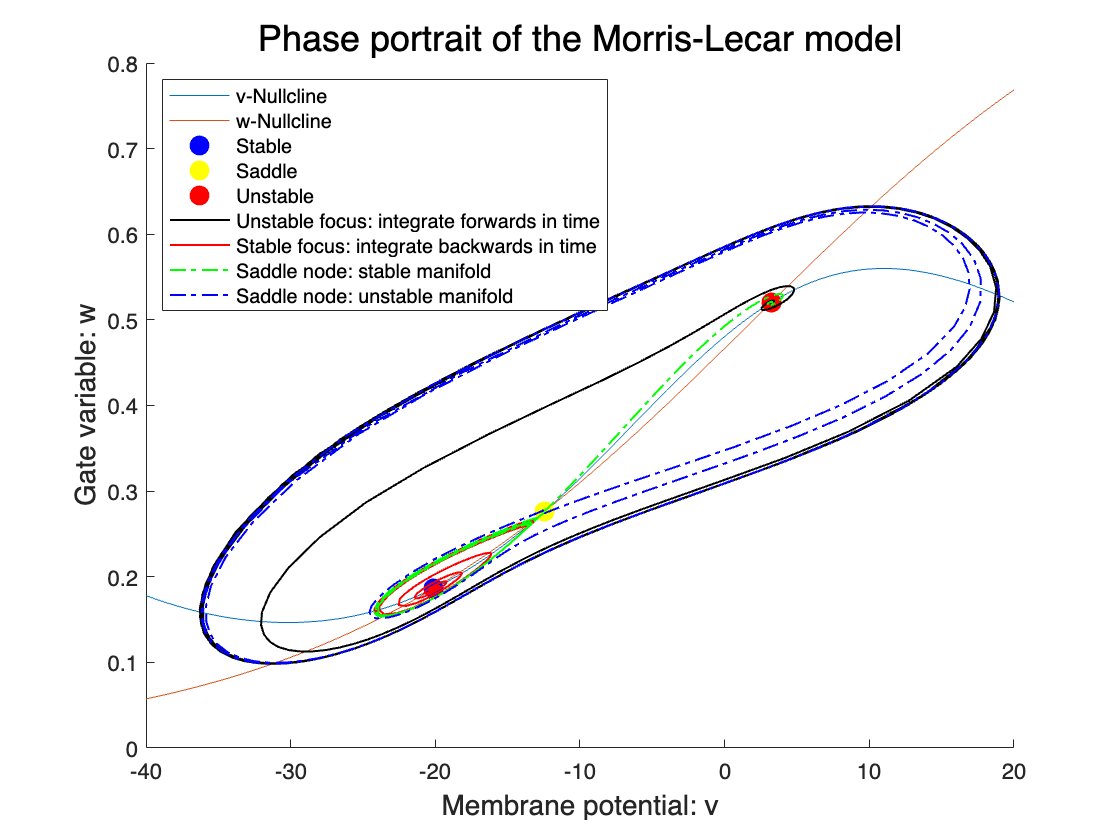

% 计算鞍点的不稳定流形（从位于不稳定特征向量方向w上鞍点两侧的初始条件计算两个正向轨迹）
tspan = [0 100];
x0 = [eq_points(2, 1), eq_points(2, 2) + 0.002];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'b', 'LineWidth', 1, 'LineStyle','-.');

x0 = [eq_points(2, 1), eq_points(2, 2) - 0.002];
[~, x] = ode45(fun, tspan, x0);
plot(x(:,1), x(:,2), 'LineWidth', 1, 'Color', 'b', 'LineWidth', 1, 'LineStyle','-.');

legend('v-Nullcline', 'w-Nullcline', 'Stable', 'Saddle', 'Unstable', '﻿Unstable focus: integrate forwards in time', '﻿Stable focus: integrate backwards in time', ...
    '﻿Saddle node: stable manifold', '', 'Saddle node: unstable manifold', '', 'Location','northwest');
hold off;

#### 与其他参数下的phase portrait的对比

EG Figure 5.10：只有一个稳定平衡点；有两条周期轨道。

EG Figure 5.12 (discussed in class)：如左下图所示。有一个稳定平衡点，一个鞍点和一个不稳定平衡点；有一条周期轨道。稳定平衡点的反向积分轨迹趋向于不稳定平衡点。鞍点的不稳定流形中的一条轨迹趋向于稳定平衡点，而另一条轨迹则趋向于周期轨道；鞍点的稳定流形的两个分支在趋向于不稳定平衡点。不稳定平衡点的正向积分轨迹趋向于周期轨道。

作业中的结果：如右下图所示。有一个稳定平衡点，一个鞍点和一个不稳定平衡点；有两条周期轨道。稳定平衡点的反向积分轨迹趋向于小的周期轨道。鞍点的不稳定流形中两条轨迹均趋向于大的周期轨道；鞍点的稳定流形中的一条轨迹趋向于小的周期轨道，另一条轨迹趋向于不稳定平衡点。不稳定平衡点的正向积分轨迹趋向于大的周期轨道。

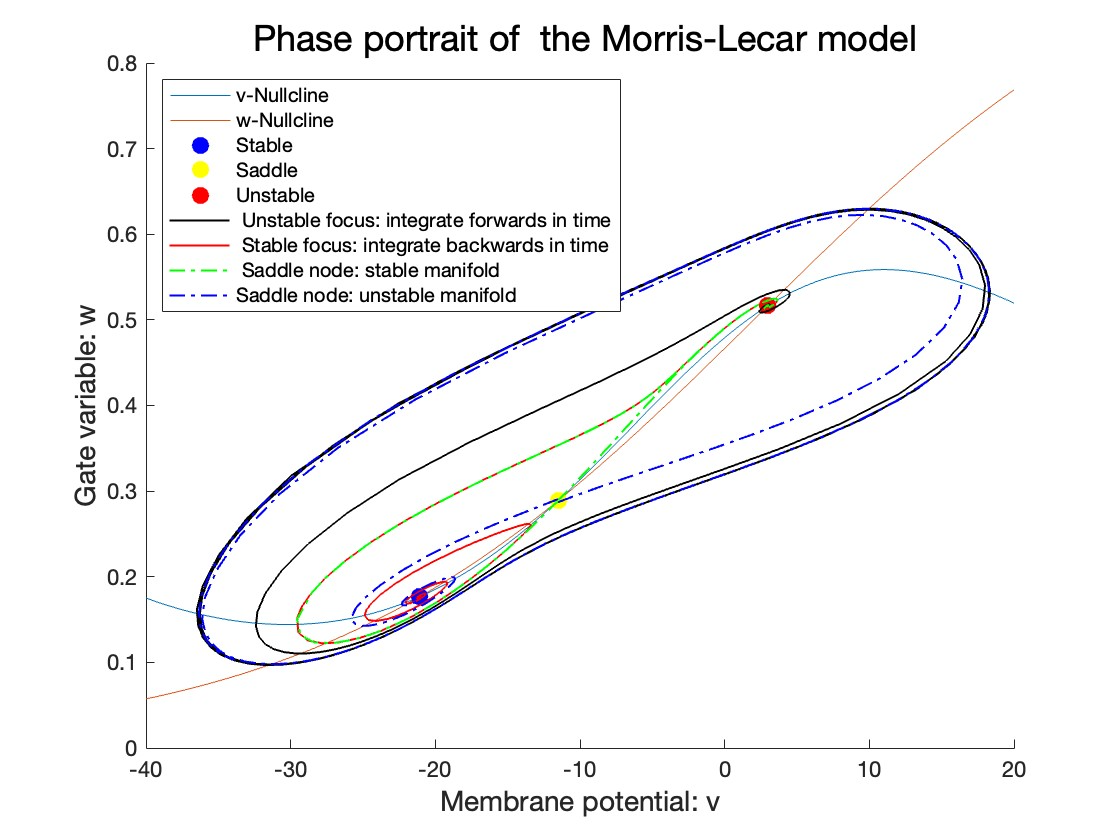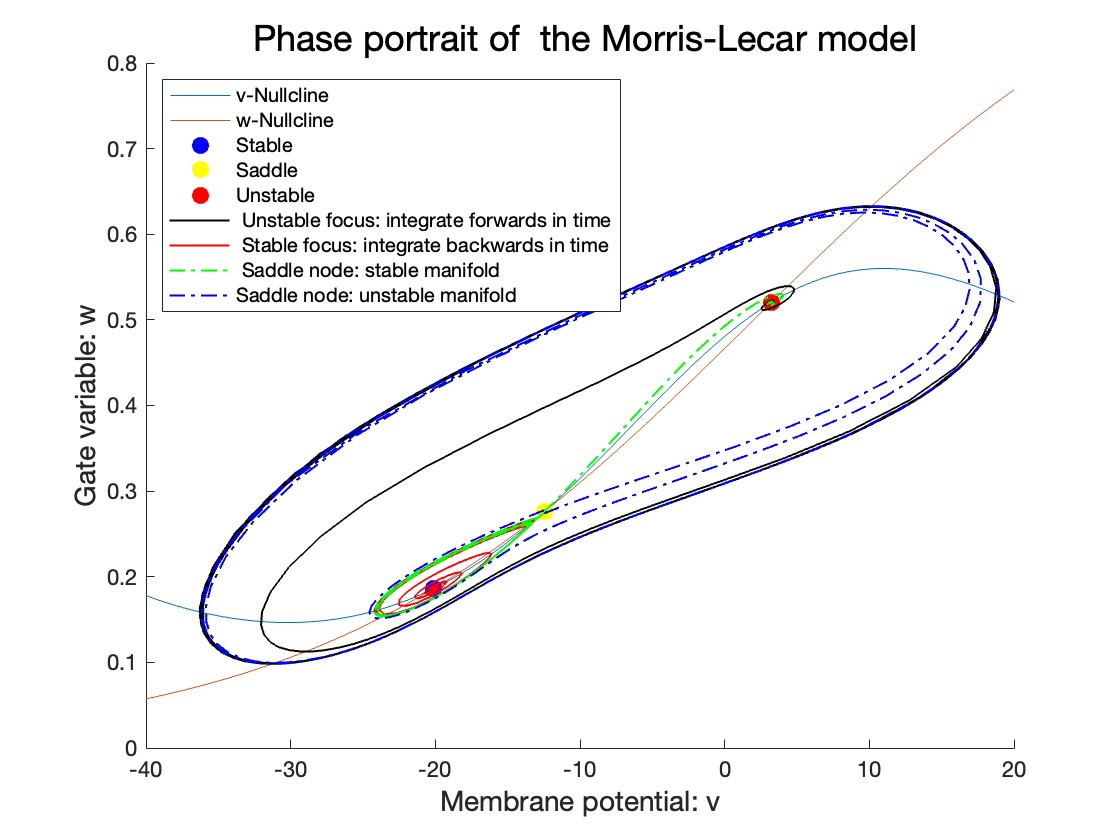

## Exercise 3

﻿**(Optional Exercise)** Let’s study a Lotka-Volterra sytem of population dynamics. Let $x_1$ be the number of prey and $x_2$ be the number of predators. As we have discussed in class, a classic model of how the two populations evolve can take the following form

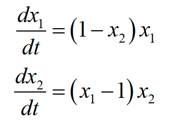

﻿Write a code to simulate these equations. What do the solutions imply is happening to the predator and prey populations over time?

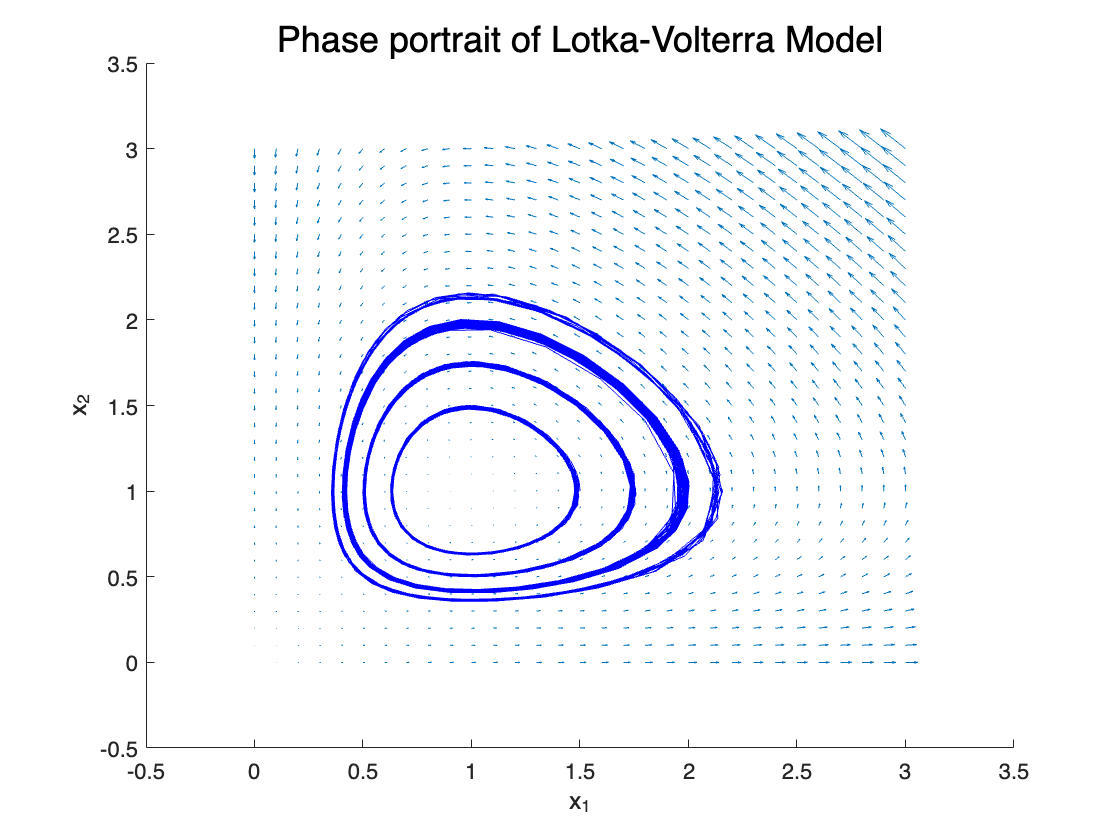

% 绘制相图
fun_t_x = @(t, x) [(1 - x(2)) * x(1); (x(1) - 1) * x(2)];
[x1, x2] = meshgrid(0:0.1:3, 0:0.1:3);
u = (1 - x2) .* x1;
v = (x1 - 1) .* x2;
figure;
hold on;
quiver(x1, x2, u, v, 1.2);
for x0 = 0.5:0.5:1.5
    for y0 = 0.5:0.5:1.5
        [t, xy] = ode45(fun_t_x, [0, 100], [x0, y0]);
        plot(xy(:, 1), xy(:, 2), 'b');
    end
end

title('Phase portrait of Lotka-Volterra Model', 'FontSize', 18);
xlabel('x_1');
ylabel('x_2');
hold off;

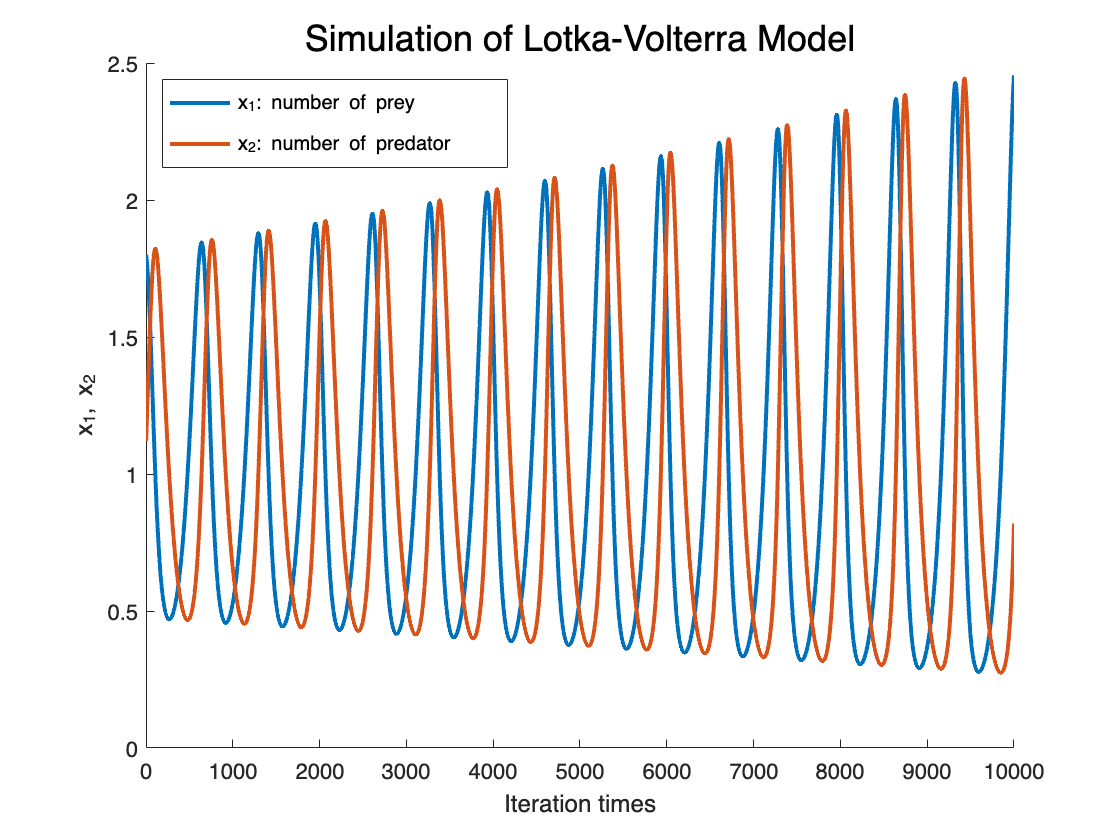

% 模拟过程
iter_max = 10000;
delta = 0.01;
x1 = 1.8;
x2 = 1.12;
res = zeros(2, iter_max);
res(1, 1) = x1;
res(2, 1) = x2;
for i = 2: iter_max
    dx1 = (1 - x2) * x1;
    dx2 = (x1 - 1) * x2;
    x1 = x1 + dx1 * delta;
    x2 = x2 + dx2 * delta;
    res(1, i) = x1;
    res(2, i) = x2;
end
figure;
hold on;
plot(res(1, :), 'LineWidth', 2);
plot(res(2, :), 'LineWidth', 2);
title('Simulation of Lotka-Volterra Model','FontSize', 18);
xlabel('Iteration times');
ylabel('x_1, x_2');
legend('x_1: number of prey', 'x_2: number of predator', 'Location', 'northwest');

对方程组的数值计算表明：随着时间推移，捕食者和被捕食者的种群数量均处在周期性波动中，且捕食者的波动滞后于被捕食者的波动。同时，二者数量波动的幅度随时间增大而逐渐增大，即最大种群数量逐渐增大，最小种群数量逐渐减小。